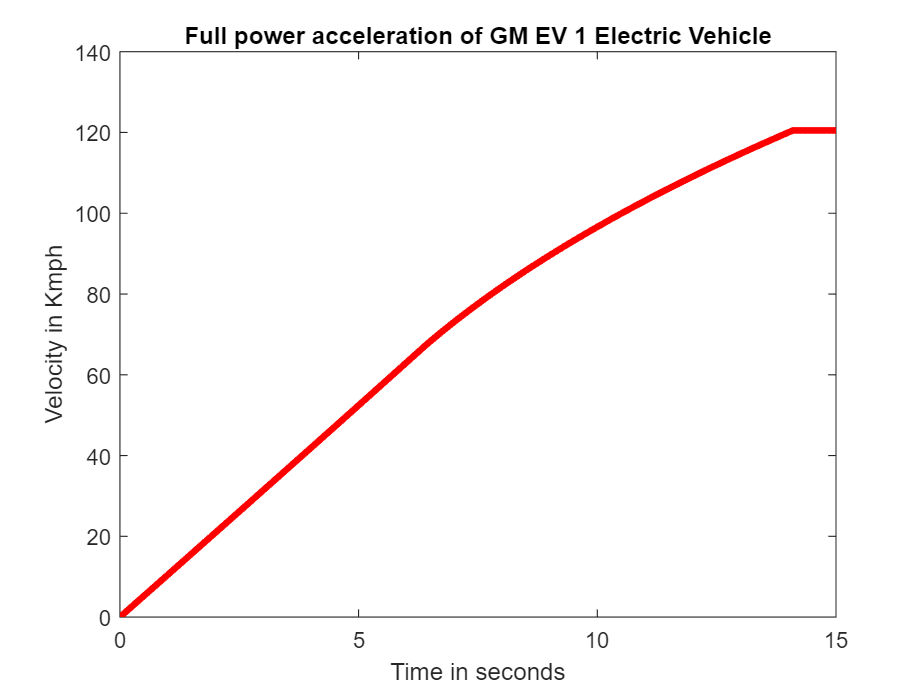

t=[0:.1:15];    % vector spaced 0.1 from 1 to 15
v=zeros(1,150); % vector made of zeros with dimension 1x150
dt=0.1;     

for n=1:150     % 150 iterations
    if v(n)<19.8   
        v(n+1)=v(n)+dt*(3.11 +(0.000137*(v(n)^2)));
    elseif v(n)>35.8
        v(n+1)=v(n);
    else
        v(n+1)=v(n)+dt*((62.1/v(n))-0.046-(0.000137*(v(n)^2)));
    end
end

v=v.*3.36;  % element wise multiplication for Kmph conversion
plot(t,v,"r-","LineWidth",3)    % plot command
xlabel("Time in seconds")       % X axis label
ylabel("Velocity in Kmph")      % Y axis label
title("Full power acceleration of GM EV 1 Electric Vehicle")    % Graph label